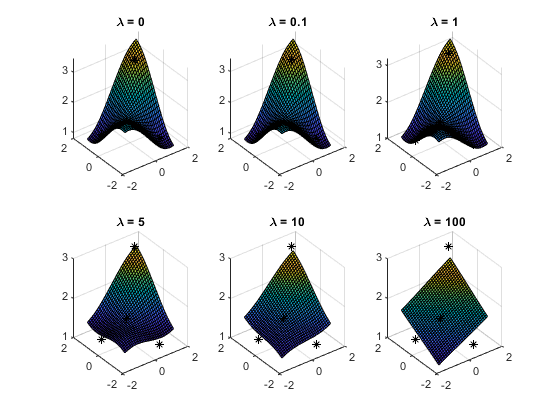

         0    2.7726    2.7726    8.3178
    2.7726         0    8.3178    2.7726
    2.7726    8.3178         0    2.7726
    8.3178    2.7726    2.7726         0



         0    2.7726    2.7726    8.3178
    2.7726         0    8.3178    2.7726
    2.7726    8.3178         0    2.7726
    8.3178    2.7726    2.7726         0



         0    2.7726    2.7726    8.3178
    2.7726         0    8.3178    2.7726
    2.7726    8.3178         0    2.7726
    8.3178    2.7726    2.7726         0



         0    2.7726    2.7726    8.3178
    2.7726         0    8.3178    2.7726
    2.7726    8.3178         0    2.7726
    8.3178    2.7726    2.7726         0



         0    2.7726    2.7726    8.3178
    2.7726         0    8.3178    2.7726
    2.7726    8.3178         0    2.7726
    8.3178    2.7726    2.7726         0



         0    2.7726    2.7726    8.3178
    2.7726         0    8.3178    2.7726
    2.7726    8.3178         0    2.7726
    8.3178    2.7726    2.7726         0



%Set datapoints
dataPoints = [1 1 3; 1 -1 1; -1 1 1; -1 -1 2];
%Define the list of regularization parameters
lambdas = [0, 0.1, 1, 5, 10, 100];
%Define the grid dimensions
meshStart = -1.5;
meshStep = 0.1;
meshEnd = 1.5;
figure("Name", "Thin plate splines regression for different values of regularization parameters lambda")
title("Thin plate splines regression for different values of regularization parameter \lambda")
set(gcf, 'Visible', 'on');
for i = 1:length(lambdas)
    [F, df] = ThinPlateSplines(dataPoints, lambdas(i), meshStart, meshStep, meshEnd);
    x = meshStart:meshStep:meshEnd;
    y = x;
    [X, Y] = meshgrid(x);
    subplot(2, 3, i);
    surf(X, Y, F), title("\lambda = " + lambdas(i));
    hold on;
    plot3(dataPoints(:, 1), dataPoints(:, 2), dataPoints(:, 3), '*', "Color", 'black');
    hold off;
end